# **TDSÑ: Práctica 2**

Antes de comenzar ejecute el siguiente código para borrar las variables del espacio de trabajo, añadir el *toolbox* del laboratorio, establecer un tamaño de gráfica por defecto y eliminar algunos avisos del editor.

clear, subplot
set(groot, 'DefaultFigurePosition', [0, 0, 500, 300])
%#ok<*NASGU>
%#ok<*ASGLU>

## **Instrucciones**

- *Escriba las direcciones de los correo-e suya y de su pareja en las variables *`alumno_1`* y *`alumno_2`* y ejecute la sección.*

- *La práctica incluye varias tareas que debe contestar en este mismo archivo en las zonas marcadas desde *`% SU CÓDIGO AQUÍ`* hasta *`% --------------.`

- *No cambie las llamadas a la función *`check_task`.

- *Cuando termine las tareas guarde este archivo y súbalo a la carpeta de entrega de Moodle. No cambie el nombre ni el tipo de archivo.*

alumno_1 = 'ignacio.aguirrec@alumnos.upm.es'; 
alumno_2 = 'ines.valdivielso@alumnos.upm.es'; 
check_task(200, 'es');

## Introducción

En general, el muestreo de señales requiere un convertidor analógico-digital (A/D o ADC *analog to digital converter*) y, en el caso de señales de audio, el uso de un micrófono o alguna otra fuente de audio externa. También se puede ilustrar el proceso usando señales con expresiones matemáticas explícitas en las que pueden tomarse valores en los instantes de tiempo $t=nT_s$ para ***calcular*** las muestras de la señal discreta. Esta es la aproximación seguida en esta práctica.

Por su parte, la reconstrucción de señales continuas a partir de sus muestras requiere un convertidor digital-analógico (D/A o DAC *digital to analog converter)* y el uso de un altavoz o auriculares. Esta operación es más sencilla y se usará en algunas secciones de la práctica.

En esta práctica también se abordan otras cuestiones relacionadas con el muestreo. En primer lugar el cambio de frecuencia de muestreo mediante procesado estrictamente digital. Para ello será necesario estudiar las operaciones de ***expansión*** y ***compresión*** como paso previo para los procesos de ***interpolación*** y ***diezmado*** que dan lugar a las señales que hubiesen resultado de un muestreo a una frecuencia mayor o menor, respectivamente.

## 1. Muestreo y reconstrucción

### 1.1. Muestreo correcto

La variable fundamental del muestreo uniforme es el periodo de muestreo $T_s$ o su inversa la frecuencia de muestreo $f_s$. Con cualquiera de estos datos se puede crear el vector de tiempos para muestrear una señal desde un instante inicial $t_0$ a un instante final $t_f$ usando el operador '`:`' (dos puntos) de MATLAB. Por ejemplo, el vector de tiempos `t` para muestrear una señal en el intervalo $-0.3\le t \le 0.3\,\mathrm{s}$ con una frecuencia de muestreo $f_s=100\,\mathrm{Hz}$ se calcula como:

fs = 100;
Ts = 1/fs;
t0 = -0.3;
tf = 0.3;
t = (t0:Ts:tf)';

Con el vector de tiempos el muestreo de un coseno de amplitud $A=3$, frecuencia $f_0=4\,\mathrm{Hz}$ y fase $\phi=\pi/3$ es sencillo:

A = 3;
f0 = 4;
phi = pi/3;
x = A*cos(2*pi*f0*t + phi);
plot_sig(t, x, 'cos(2\pi4t)', 't')

La función [`plot_sig`](matlab: help plot_sig) del *toolbox* facilita la representación de las señal.

#### **Tarea 2.1.1**

Cree el vector de tiempos `t` para muestrear una señal en el intervalo $0\le t \le 1.5\,\mathrm{ms}$ con una frecuencia de muestreo $f_s=250\,\mathrm{kHz}$.

% SU CÓDIGO AQUÍ
fs = 250*(10^3);
Ts = 1/fs;
t0=0;
tf=1.5*(10^-3);
t = (t0:Ts:tf)';
% --------------
check_task(211, 'es');

>>>>> [2:1:1] Correcto.


En lugar de un vector de tiempos puede calcularse un vector de índices $n$ (ya que $t = nT_s$) teniendo cuidado para que los valores sean enteros. Por ejemplo, el vector de índices `n` para muestrear una señal en el intervalo $-0.3\le t \le 0.3\,\mathrm{s}$ con una frecuencia de muestreo $f_s=100\,\mathrm{Hz}$ se calcula como:

fs = 100;
Ts = 1/fs;
n0 = round(-0.3*fs);
nf = round(0.3*fs);
n = (n0:nf)';

Nótese que en este caso el paso entre valores del vector de índices es 1.

Con el vector de índices el muestreo del coseno anterior es igual de sencillo:

x = A*cos(2*pi*f0*n*Ts + phi);
plot_sig(n, x, 'cos(2\pi4nT_{s})', 'n')

#### **Tarea 2.1.2**

Cree el vector de índices `n` para muestrear una señal en el intervalo $5\le t \le 15\,\mathrm{ms}$ con una frecuencia de muestreo $f_s=250\,\mathrm{kHz}$.

% SU CÓDIGO AQUÍ
Ts = 1/fs;
fs = 250*(10^3);
n0 = round(5*(10^-3)*fs);
nf = round(15*(10^-3)*fs);
n = (n0:nf)';
% --------------
check_task(212, 'es');

>>>>> [2:1:2] Correcto.


El vector de tiempos es apropiado cuando se desea resaltar que una señal proviene de un muestreo, mientras que el vector de índices es apropiado para resaltar el carácter discreto de una señal.

El muestreo puede entenderse más fácilmente en el dominio de la frecuencia. La función [`dtft`](matlab: help dtft) del *toolbox* calcula y, opcionalmente, dibuja la transformada de Fourier de la señal discreta de entrada en el intervalo de frecuencias positivas. Si se usa sin parámetros de salida la función [`dtft`](matlab: help dtft) dibuja la magnitud en decibelios de la transformada.

dtft(x)

#### **Tarea 2.1.3**

Calcule la señal discreta 𝑥[𝑛]=𝑥(𝑛𝑇𝑠) resultado de muestrear a frecuencia $f_s=5\,\mathrm{kHz}$ la señal continua $x(t)=\cos(2\pi 200 t) + 0.5\sin(2\pi 1000 t + \pi/6)$ en el intervalo de tiempo $0\le t \le 20\,\mathrm{ms}$. Asigne el vector de tiempos a la variable `t` y los valores de la función a la variable `x`.

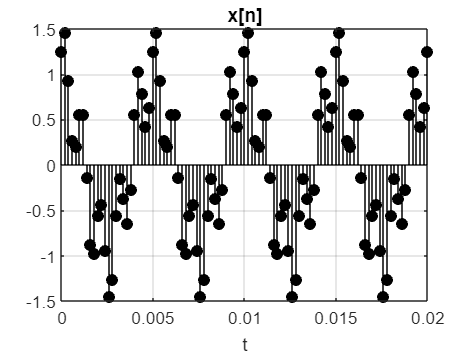

% SU CÓDIGO AQUÍ
fs=5*(10^3);
Ts=1/fs;
t0=0;
tf=20*(10^-3);
t = (t0:Ts:tf)';
x = cos(2*pi*200*t) + 1/2*sin(2*pi*1000*t + pi/6); 
% --------------
plot_sig(t, x, 'x[n]', 't')

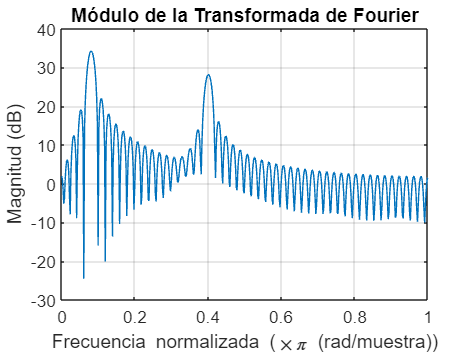

dtft(x);

check_task(213, 'es');

>>>>> [2:1:3] Correcto.


### 1.2. Muestreo con solapamiento

De acuerdo con el teorema de Nyquist la frecuencia de muestreo determina la frecuencia máxima $f_m$ que puede contener una señal para que se pueda muestrear sin solapamiento: $f_s > 2f_m$.

Si se muestrean las sinusoides continuas $x_1(t)=\cos(2\pi 1575t)$ y $x_2(t)=\cos(2\pi 3425t)$ a frecuencia $f_s=5\,\mathrm{kHz}$ en el intervalo temporal $0\le t \le 45\,\mathrm{ms}$ y se representan las 30 primeras muestras se observa que las señales discretas correspondientes son indistinguibles porque tienen exactamente las mismas muestras.

fs = 5e3;
Ts = 1/fs;
t0 = 0;
tf = 45e-3;
f1 = 1575;
f2 = 3425;
nf = round(tf*fs);
n = (0:nf)';
x1 = cos(2*pi*f1*n*Ts);
x2 = cos(2*pi*f2*n*Ts);
subplot(211), plot_sig(n(1:30), x1(1:30), 'x_{1}[n]', 'n')
subplot(212), plot_sig(n(1:30), x2(1:30), 'x_{2}[n]', 'n')

El segundo coseno no está bien muestreado por lo que $x_2[n]$ es una señal alias. Evidentemente sus espectros también son idénticos.

subplot(211), dtft(x1);
subplot(212), dtft(x2);

En esta sección puede ver el efecto del solapamiento con un único seno. Moviendo el control deslizante se cambia la frecuencia $f_0$ de un seno muestreado a $fs=8\,\mathrm{kHz}$.

Si se aumenta la frecuencia desde $f_0 = 0$ se observa que el espectro refleja correctamente la señal hasta $f_0=4\,\mathrm{kHz}$, frecuencia a la que el espectro se anula porque todas mas muestras son 0. Si sigue aumentando la frecuencia $f_0$ el espectro mostrará la señal alias.

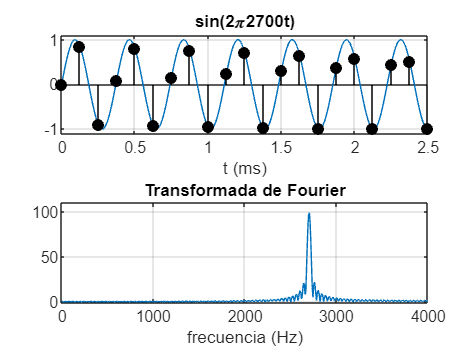

f0 =2700;
sin_alias(f0)

La señal reconstruida por un convertidor D/A siempre será la señal bien muestreada o su alias. Este comportamiento puede ilustrarse con una señal de tipo *chirp* que es un barrido continuo de una sinusoide desde una frecuencia a otra en un intervalo de tiempo. Por ejemplo, la señal *chirp* en el intervalo de frecuencias $1 \le f \le 3\,\mathrm{kHz}$ en $2\,\mathrm{s}$ se calcula y se escucha con

fs = 8e3; Ts = 1/fs; t0 = 0; t1 = 2; t = (t0:Ts:t1)';
y = chirp(t, 1e3, t1, 3e3);
soundsc(y, fs, [-10, 10])

La frecuencia de la señal reconstruida es siempre creciente porque se verifica la condición de Nyquist.

Si el rango de frecuencias es ahora $3 \le f \le 5\,\mathrm{kHz}$ en el primer segundo se cumple la condición de Nyquist y la frecuencia se escucha como creciente. En el segundo segundo ya no se cumple y la frecuencia se escucha como decreciente.

fs = 8e3; Ts = 1/fs; t0 = 0; t1 = 2; t = (t0:Ts:t1)';
y = chirp(t, 3e3, t1, 5e3);
soundsc(y, fs, [-10, 10])

#### Tarea 2.1.4

Calcule la señal discreta 𝑥[𝑛]=𝑥(𝑛𝑇𝑠) resultado de muestrear a frecuencia $f_s=5\,\mathrm{kHz}$ la señal continua $x(t)=\sin(2\pi 1575t)+\sin(2\pi 3425t)$ en el intervalo de tiempo $-10\le t \le 10\,\mathrm{ms}$. Asigne el vector de índices a la variable `n` y los valores de la función a la variable `x`.

Calcule también la potencia de la señal en el intervalo de muestreo: $\displaystyle P_x = \frac{1}{L}\sum_{n=n_i}^{n_f}\left|x[n]\right|^2$, con $n_i$ y $n_f$ los índices de la primera y última muestras, respectivamente y $L$ la longitud en muestras del intervalo. Asigne el resultado a la variable `Px`.

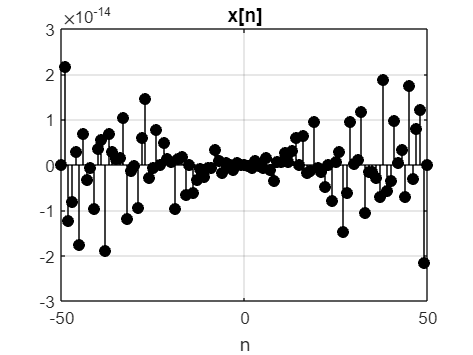

% SU CÓDIGO AQUÍ
x = sin(2*pi*1575*n*Ts) + sin(2*pi*3425*n*Ts);
fs=5e3;
Ts=1/fs;
t0=-10e-3;
tf=10e-3;
t = (t0:Ts:tf)';
n0 = round(t0*fs);
nf = round(tf*fs);
n = (n0:nf)';
Px = (1/size(n,1))*sum(x.^2); 

% --------------
plot_sig(n, x, 'x[n]', 'n')

check_task(214, 'es');

>>>>> [2:1:4] Correcto.


## 2. Cambio de frecuencia de muestreo

### 2.1. Compresión y diezmado

El siguiente código genera una señal $x[n]$ con dos tonos a $300\,\mathrm{Hz}$ y $3\,\mathrm{kHz}$ muestreada a frecuencia $f_s=24\,\mathrm{kHz}$ en el intervalo $0\le t \lt 2\,\mathrm{s}$. Se quiere reducir la frecuencia de muestreo por un factor $M=6$, es decir a $f_{sM}=fs/M = fs/6 = 4\,\mathrm{kHz}$.

Si se comprime la señal el tono a $3\,\mathrm{kHz}$ producirá solapamiento porque está por encima de la nueva frecuencia de Nyquist.

fs = 24000; Ts = 1/fs;
n = (0:2/Ts-1)';
x = cos(2*pi*300*n*Ts) + cos(2*pi*3000*n*Ts);
dtft(x, fs); ylim([0, 90])
xline(2, "r--", "Nueva frecuencia de Nyquist")

En este caso se ha usado la función [`dtft`](matlab: help dtft) con el periodo de muestreo para que la transformada se muestre en $\mathrm{Hz}$.

Para comprimir la señal discreta se puede usar la función [`downsample`](matlab: doc downsample), indicando el factor de muestreo $M$ (que debe ser entero).

M = 6; fsM = fs/M;
x_down = downsample(x, M);
dtft(x_down, fsM); ylim([0, 80])

Nota: el módulo del espectro se ha reducido $20\log_{10}(M)\approx15.6\,\mathrm{dB}$ porque la longitud de la señal se ha dividido por $M$.

El tono a $300\,\mathrm{Hz}$ está en la posición correcta pero el tono a $3\,\mathrm{kHz}$ ha mutado en un alias a $1\,\mathrm{kHz}$. Para reducir el alias se puede usar un filtro antisolapamiento antes del compresor. Una forma sencilla de hacer el filtrado es con la función [`lowpass`](matlab: doc lowpass) que diseña un filtro paso bajo y filtra la señal de entrada. Como el filtro que se usa no es muy bueno es preferible usar como frecuencia de corte $f_{sM}/3$ en lugar de la frecuencia de Nyquist $f_{sM}/2$.

x_filt = lowpass(x, fsM/3, fs);
x_M = downsample(x_filt, M);
dtft(x_M, fsM); ylim([0, 80])

La amplitud del tono alias se ha reducido unos $60\,\mathrm{dB}$.

Todo este proceso puede hacerse en un único paso con la función [`decimate`](matlab: doc decimate) que usa un filtro con mejor respuesta en frecuencia antes de comprimir la señal.

x_M = decimate(x, M);
dtft(x_M, fsM); ylim([0, 80])

El tono alias a $1\,\mathrm{kHz}$ sigue estando presente pero su nivel se ha reducido unos $130\,\mathrm{dB}$, mucho más que con el filtro antialiasing de la función [`lowpass`](matlab: doc lowpass).

A continuación puede escuchar $1\,\mathrm{s}$ de la señal original con los dos tonos, la señal comprimida con el tono alias y la señal diezmada correctamente.

soundsc(x(1:fs), fs)
pause(1.2)
soundsc(x_down(1:fsM), fsM)
pause(1.2)
soundsc(x_M(1:fsM), fsM)
pause(1.2)

Note que la señal se percibe como un único tono porque el tono alias es inaudible.

#### Tarea 2.2.1

El archivo `speech_24k.wav` contiene un segmento de habla muestreado a $24\,\mathrm{kHz}$. Use la función [`audioread`](matlab: doc audioread) para leer la señal del fichero de audio y reduzca su frecuencia de muestreo a $8\,\mathrm{kHz}$ con [`decimate`](matlab: doc decimate). Asigne la señal diezmada a la variable `y`.

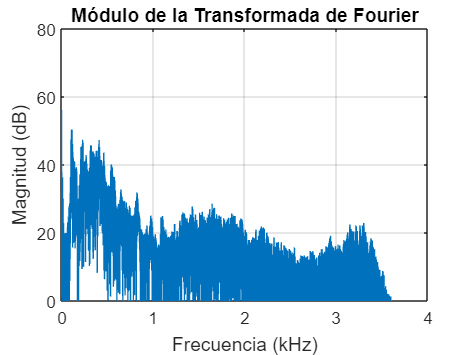

% SU CÓDIGO AQUÍ
[s, fs] = audioread('speech_24k.wav');
fs=24e3;
M=3; fsM = fs/M;
x_M = decimate(x, M);
dtft(x_M, fsM); ylim([0, 80]);

y=x_M;

% --------------
check_task(221, 'es')

>>>>> [2:2:1] Correcto.


soundsc(s, fs), pause(5)
soundsc(y, fs/M), pause(5)

### 2.2. Expansión e interpolación

El siguiente código genera una señal $x[n]$ con un tono a $1.2\,\mathrm{kHz}$ muestreada a frecuencia $f_s=3\,\mathrm{kHz}$ en el intervalo $0\le t \lt 1\,\mathrm{s}$. Se quiere aumentar la frecuencia de muestreo por un factor $L=6$, es decir a $f_{sL}=fsL = 6fs = 18\,\mathrm{kHz}$.

fs = 3e3;
Ts = 1/fs;
n = (0:1*fs)';
x = cos(2*pi*1200*n*Ts);
dtft(x, fs);

Para expandir la señal se puede usar la función [`upsample`](matlab: doc upsample), indicando el factor de expansión $L$ (que debe ser entero).

L = 6;
fsL = fs*L;
x_up = upsample(x, L);
dtft(x_up, fsL);

El tono en $1.2\,\mathrm{kHz}$ está en la posición correcta pero los que aparecen por encima de ese valor son imágenes indeseadas del tono que hay que eliminar. Para reducir las imágenes se puede usar un filtro antiimagen después del expansor usando la función [`lowpass`](matlab: doc lowpass). Como el filtro no es muy bueno es preferible usar como frecuencia de corte $f_{s}/3$ en lugar de la frecuencia de Nyquist $f_{s}/2$.

x_L = lowpass(x_up, fs/3, fsL);
dtft(x_L, fsL)

La amplitud de la primera imagen se ha reducido unos $13\,\mathrm{dB}$; la de los tonos restantes unos $70\,\mathrm{dB}$.

Todo este proceso puede hacerse en un único paso con la función [`interp`](matlab: doc interp) que usa un filtro con distinta respuesta en frecuencia después de expandir la señal.

x_L = interp(x, L);
dtft(x_L, fsL);

Ahora la amplitud de la primera imagen se ha reducido solo unos $13\,\mathrm{dB}$ y la de los tonos restantes solo unos $18\,\mathrm{dB}$. Es evidente que la estrategia de diseño de esta función puede no ser la más adecuada.

A continuación puede escuchar la señal original con un tono, la señal expandida con los tonos imagen y la señal interpolada.

soundsc(x, fs)
pause(1.2)
soundsc(x_up, fsL)
pause(1.2)
soundsc(x_L, fsL)
pause(1.2)

Note que, a pesar de la reducción de nivel, los tonos imagen en la señal interpolada aún pueden escucharse.

#### Tarea 2.2.2

El archivo `speech_8k.wav` contiene un segmento de habla muestreado a $8\,\mathrm{kHz}$. Use la función [`audioread`](matlab: doc audioread) para leer la señal del fichero de audio y aumente su frecuencia de muestreo a $32\,\mathrm{kHz}$ con la función [`interp`](matlab: doc interp). Asigne la señal interpolada a la variable `y.`

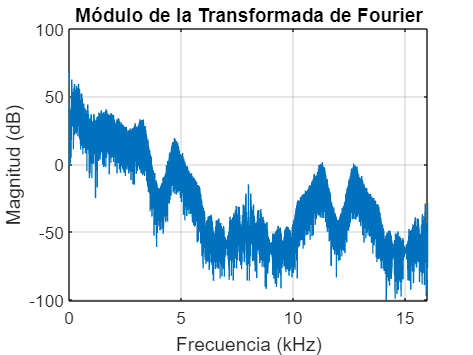

% SU CÓDIGO AQUÍ
[s, fs] = audioread('speech_8k.wav');
fs=8e3; 
L = 4;
fsL = fs*L;
x_L = interp(x, L);
dtft(x_L, fsL);

y = x_L;
% --------------
soundsc(s, fs), pause(5)
soundsc(y, fs*L), pause(5)
check_task(222, 'es')

>>>>> [2:2:2] Correcto.


### 2.3. Cambio de frecuencia de muestreo fraccionario

Cuando el factor de cambio de la frecuencia de muestreo no es un número entero, se puede proceder en dos pasos: interpolación seguida de diezmado, siempre en este orden para preservar el contenido frecuencial correcto.

La función [`resample`](matlab: doc resample) implementa este proceso pero deben indicarse por separado los factores de interpolación y diezmado. Para calcular estos valores puede ser útil la función [`rat`](matlab: doc rat) que hace una aproximación racional del argumento.

Por ejemplo para cambiar la frecuencia de muestreo de un tono de $2.5\,\mathrm{kHz}$ muestreado a frecuencia $f_s=10\,\mathrm{kHz}$ a la frecuencia $f_{L/M}=18\,\mathrm{kHz}$ se puede hacer lo siguiente:

fs = 10e3;
Ts = 1/fs;
n = (0:0.5*fs)';
x = cos(2*pi*2500*n*Ts);
f_LM = 18e3;
[L, M] = rat(f_LM/fs);
x_LM = resample(x, L, M);
dtft(x, fs)
dtft(x_LM, f_LM)

#### Tarea 2.2.3

El archivo `speech.wav` contiene un segmento de habla muestreado a $22.05\,\mathrm{kHz}$. Use la función [`audioread`](matlab: doc audioread) para leer la señal del fichero de audio y aumente su frecuencia de muestreo a $24\,\mathrm{kHz}$ con [`resample`](matlab: doc resample). Asigne la señal remuestreada a la variable `y`.

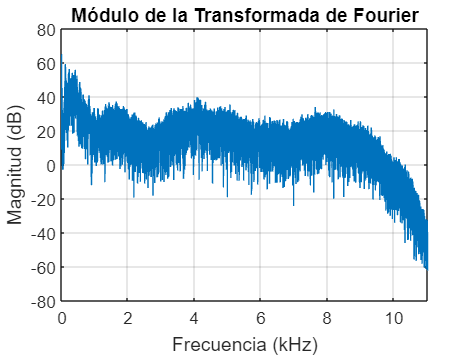

% SU CÓDIGO AQUÍ
[s, fs] = audioread('speech.wav');
fs = 22.05e3;
Ts = 1/fs;
f_LM = 24e3;
[L, M] = rat(f_LM/fs);
x_LM = resample(s, L, M);
dtft(s, fs)

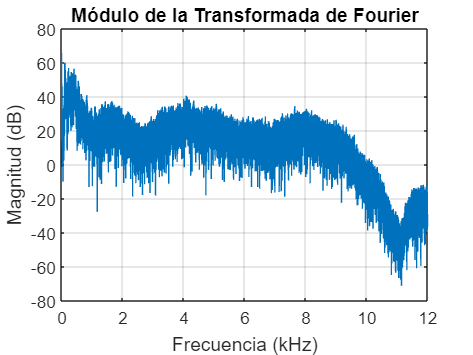

dtft(x_LM, f_LM)

y = x_LM;
% --------------
check_task(223, 'es')

>>>>> [2:2:3] Correcto.


soundsc(s, fs), pause(5)
soundsc(y, fs*L/M), pause(5)

#### Tarea 2.2.4

Considere la señal discreta $x[n]=\cos\left(\frac{4\pi}{5} n\right)$ que se procesa con el esquema de la figura,

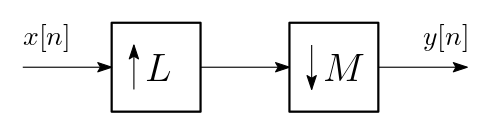

en el que $L=5$ y $M=3$, para obtener la señal $y[n]$.

Calcule la señal $y[n]$ en el intervalo $0\le n \le 1250$.

% SU CÓDIGO AQUÍ
x = cos(4/5*pi*n);
n0 = 0;
nf = 1250;
n = (n0:nf)';
M = 3;
L = 5;
y = resample(x, L ,M);


% --------------
check_task(224, 'es')

>>>>> [2:2:4] Correcto.


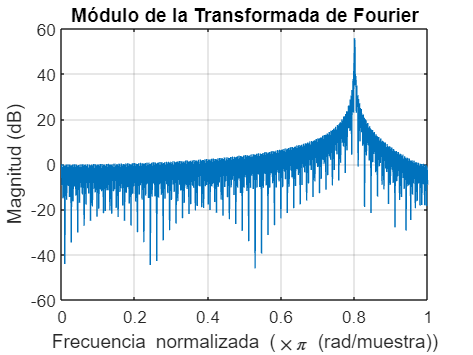

dtft(x)

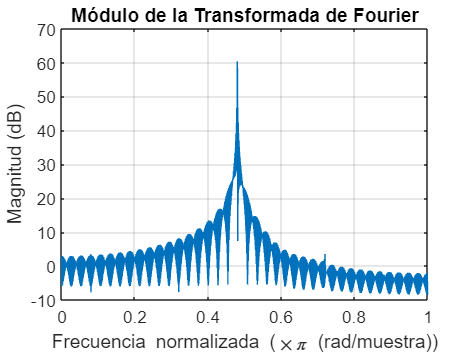

dtft(y)

## 3. Algunas cuestiones prácticas

### 3.1. Procesado no lineal

Una señal bien muestreada puede producir solapamiento si se procesa con algún procedimiento no lineal. La no linealidad implica la aparición de nuevo contenido frecuencial que puede exceder el intervalo de Nyquist. Por ejemplo, la señal continua $x(t)=\cos(2\pi 100t)$ muestreada a $f_s=250\,\mathrm{Hz}$ da lugar a la señal discreta $x[n]=\cos(0.8\pi n)$. Si la señal se eleva al cuadrado el resultado debería ser $y[n]=0.5+0.5\cos(1.6\pi n)$, pero la nueva frecuencia es mayor que $\pi$ por lo que se refleja como un alias a frecuencia $0.4\pi$ además de la componente continua.

Con el siguiente código puede observar la magnitud del espectro del resultado de muestrear una sinusoide `x` de frecuencia $f_0$ (que se puede variar con el control deslizante) y calcular $y[n]=2x^2[n]-1$.

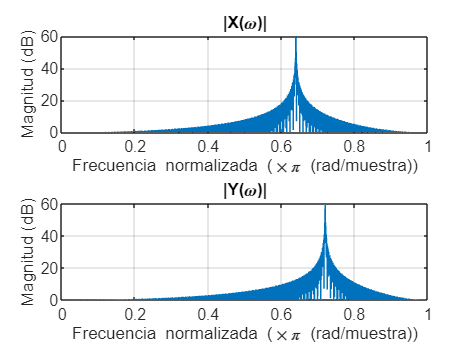

f0 = 80;
fs = 250;
Ts = 1/fs;
tf = 10;
n = (0:Ts:tf)'/Ts;
x = cos(2*pi*f0*n*Ts);
y = 2*x.^2 - 1;
subplot(211), dtft(x), title('|X(\omega)|'), ylim([0, 60])
subplot(212), dtft(y), title('|Y(\omega)|'), ylim([0, 60])

subplot

Observe cómo se produce solapamiento para frecuencias $f_0 > f_s/4$, aunque la señal esté bien muestreada.

Algunas operaciones aparentemente inocentes pueden dar lugar a graves consecuencias espectrales. Es el caso, por ejemplo, del valor absoluto. Aplicado a una sinusoide genera una señal periódica con serie de Fourier infinita por lo que siempre generará componentes alias, con independencia de la frecuencia del coseno:


$$y[n]=\left|A\cos(\omega_0 n)\right| = \frac{2A}{\pi}-\frac{4A}{\pi}\sum_{k=1}^{\infty}\frac{\cos(k\omega_0 n)}{4k^2-1}$$


n = (0:2500)';
x = cos(0.08*pi*n);
y = abs(x) - 2/pi;
dtft(y), title('|Z(\omega)|'), ylim([0, 60])

#### Tarea 2.3.1

Use la función [`sign`](matlab: doc sign) para crear la onda cuadrada $z[n]$ a partir de la sinusoide $x[n]=\cos(0.25\pi n)$ en el intervalo $0\le n \le 2000$. Dibuje su transformada de Fourier con la función [`dtft`](matlab: help dtft).

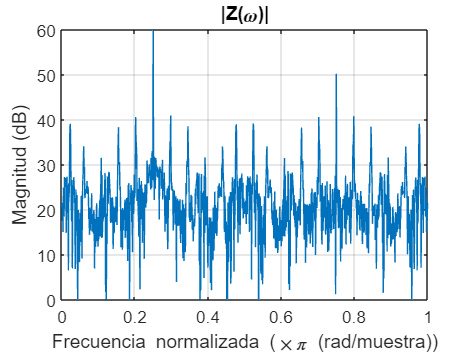

% SU CÓDIGO AQUÍ
x = cos(1/4*pi*n);
n0=0;
nf=2000;
n = (n0:nf)';
z = sign(x);
dtft(z), title('|Z(\omega)|'), ylim([0, 60])

% --------------
check_task(231, 'es')

>>>>> [2:3:1] Correcto.


### 3.2. Cuantificación

La función [`quantz`](matlab: help quantz) implementa un cuantificador uniforme bipolar con redondeo, margen dinámico $\pm X_m$ y $N\,\mathrm{bits}$. La función devuelve en `xq` la señal cuantificada.

La función de transferencia con $N=4\,\mathrm{bits}$ puede dibujarse con:

N = 4;
Xm = 2^(N-1)-1;
x = linspace(-Xm-1, Xm, 1000);
xq = quantz(x, N, Xm);
plot(x, xq), grid on
xlabel("Entrada: x[n]"), ylabel("Salida: xq[n]")
title("Cuantificación con N = " + N)
ylim([-Xm-1, Xm+1]), xlim([-Xm-1, Xm])

Dibujamos ahora una sinusoide continua $x(t)$ en azul, sus muestras sin cuantificar $x[n]$ en negro y sus muestras cuantificadas $x_q[n]$ con $N=4\,\mathrm{bits}$ en verde:

Xm = 1;
N = 4;
Ts = 0.25;
Tmax = 6;
f0 = 0.27;
t = linspace(0, Tmax)';
n = (0:Ts:Tmax)'/Ts;
xc = cos(2*pi*f0*t - 0.025);
xd = cos(2*pi*f0*n*Ts - 0.025);
xq = quantz(xd, N, Xm);
Ym = Xm*(Xm >= 1) + (Xm < 1);
plot(t, xc), grid on
xlabel('t')
hold on
stem(n*Ts, xd, 'k', 'filled');
stem(n*Ts, xq, 'g', 'filled');
hold off
legend('x(t)', 'x[n]', 'x_q[n]') 

Por último, se representa el error de cuantificación de la sinusoide, es decir, la diferencia $e[n] = x[n] - x_q[n]$:

e = xq - xd;
stem(n*Ts, e, 'k', 'filled'), grid on
xlabel('n'), title('Error de cuantificación')

La relación señal a ruido de cuantificación (en $\mathrm{dB}$) se define como


$$\mathrm{SNR}_Q=10\log_{10}\left(\frac{\sigma_x^2}{\sigma_e^2}\right)$$


con $\sigma_x^2$ la potencia de la señal y $\sigma_e^2$ la potencia del ruido de cuantificación. Aplicando el modelo de ruido aditivo se obtiene la expresión general:

with $\sigma_x^2$ the signal power and $\sigma_e^2$ the quantization noise power. Applying the additive noise model, the general expression is obtained:


$$\mathrm{SNR}_Q = 6.02N + 4.77 - 20\log_{10}\left(\frac{X_m}{\sigma_x} \right)$$


resultado de la sustitución $\sigma_e^2 = \Delta^2/12$ en la expresión de la definición.

En esta sección se carga la señal `x` contenida en el archivo `speech.wav` y se recuantifica con $N\,\mathrm{bits}$. Como la señal original está muestreada con $16\,\mathrm{bits}$ y sin saturación se usa como si fuera una señal muestreada idealmente.

Cambie el valor de $N$ y compruebe que el ruido es perfectamente audible para valores pequeños y disminuye progresivamente cuando su valor crece.

Xm = 1;
[x, fs] = audioread('speech.wav');
N = 13;
clear sound
xq = quantz(x, N, Xm);
SNRQ = 6.02*N + 4.77 - 20*log10(Xm/sqrt(x'*x/length(x)));
soundsc(xq, fs)

#### Tarea 2.3.2

Calcule la relación señal a ruido de cuantificación de la señal `x` contenida en el archivo `speech_24k.wav` cuantificada con $N=12\,\mathrm{bits}$. Para ello:

- cuantifíquela con la función [`quantz`](matlab: help quantz)`,` con $X_m=1$,

- calcule el error de cuantificación $e[n]=x[n]-x_q[n]$ con $x_q[n]$ la señal cuantificada,

- calcule la potencia de la señal $\sigma_x^2$ y asígnela a la variable `Px`,

- calcule la potencia del ruido de cuantificación $\sigma_e^2$ y asígnela a la variable `Pe`,

- calcule la relación señal a ruido de cuantificación aplicando la fórmula $\mathrm{SNR_Q}=10\log_{10}\left(\frac{\sigma_x^2}{\sigma_e^2}\right)$ y asígnela a la variable `SNRQ`.

[x, fs] = audioread('speech_24k.wav');
% SU CÓDIGO AQUÍ
Xm=1;
N=12;
Ts=1/fs;
Tmax=6;
n= (0:Ts:Tmax)'/Ts;
xq = quantz(x, N, Xm);
e = x - xq;
Px = x'*x/length(x);
Pe = e'*e/length(e);
SNRQ = 10*log10(Px/Pe);

% --------------
check_task(232, 'es')

>>>>> [2:3:2] Correcto.


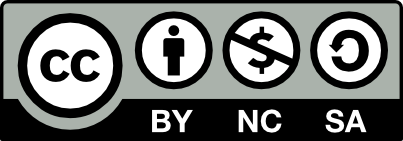 Práctica 2 © 2024 por José Parera licenciada bajo [CC BY-NC-SA 4.0](https://creativecommons.org/licenses/by-nc-sa/4.0/?ref=chooser-v1)